# Especificação de comunicação SCPI implantada no appColeta

O instrumento controlado pelo appColeta precisa ser descrito em "/Settings/GeneralSettings.json". Após a refatoração do projeto, esse arquivo estará em "src/config/GeneralSettings.json".

Nessa descrição, devem constar CINCO comandos de coleta (GET) que retornam *strings*:

- **GET1 - Identificação** (*string*): "*IDN?"

- **GET2 - Configuração varredura** (*string separadas por ";"*): "TRACe1:MODE?;:AVERage:TRACe1:STATe?;:AVERage:TRACe1:COUNt?;:DETector:TRACe1:FUNCtion?;:UNIT:POWer?;:FREQuency:STARt?;:FREQuency:STOP?;:BANDwidth:RESolution:AUTO?;:BANDwidth:RESolution?;:POWer:RF:HSENsitive?;:POWer:RF:ATTenuation:AUTO?;:POWer:RF:ATTenuation?;:SWEep:TIME?;:BANDwidth:VIDeo?"

- **GET3 - Atenuação** (*string*): "POWer:RF:ATTenuation?"

- **GET4 - GPS** (*string*): "SYSTem:GPSinfo?"

- **GET5 - Erro** (*string*): "SYSTEM:ERROR?"

UM comando de coleta (GET) que retorna um bloco binário*:*

- **GET6 - Varredura** (*bloco binário, cabeçalho + níveis em float32*): "INITiate:IMMediate;*WAI;:TRACe:DATA? TRACe1"

E, por fim, TRÊS comandos de configuração (POST):

- **POST1 - Reinicialização**: "*RST"

- **POST2 - Inicialização**: "*CLS;:DISPlay:GENeral:MEASview:SELect SPEC;:FORMat:DATA BIN;:SYSTem:GPS INT"

- **POST3 - Configuração varredura**: "TRACe1:SPECtrum:FUNCtion %Trace%;:TRACe1:SPECtrum:AVERage:COUNt %AverageCount%;:TRACe1:SPECtrum:DETection %Detector%;:UNIT:POWer %LevelUnit%;:SPECtrum:FREQuency:START %FreqStart%;:SPECtrum:FREQuency:STOP %FreqStop%;:SPECtrum:BANDwidth:RESolution %ResolutionValue%;:INPut:GAIN:STATe %Preamp%"

Além disso, precisam ser mapeadas as seguintes características:

- Tipo de traço: "ClearWrite" | "Average" | "MinHold" | "MaxHold"

- Tipo de detectores: "Sample" | "Average/RMS" | "Positive Peak" | "Negative Peak"

- Número de pontos: 461

- RBW: "1.000 kHz,3.000 kHz,10.000 kHz,30.000 kHz,100.000 kHz,300.000 kHz,1000.000 kHz,3000.000 kHz"

- VBW: "1.000 kHz,3.000 kHz,10.000 kHz,30.000 kHz,100.000 kHz,300.000 kHz,1000.000 kHz,3000.000 kHz"

- Atenuações: "0 dB,5 dB,10 dB,15 dB,20 dB,25 dB,30 dB,35 dB,40 dB,45 dB,50 dB"

- Tempo que instrumento demora na reinicialização: 1 (em segundos)

- Tempo que instrumento demora p/ configurar os seus parâmetros: 0.1 (em segundos)

- Modos de sincronização: "Single Sweep" | "Continuous Sweep"

# ## Conexão ##

% Tektronix SA2500
socket = tcpclient('localhost', 34835);
configureTerminator(socket, 'LF')

# ## Funções auxiliares ##

function spec = AppColetaConfigFile(idn)

idnBinary = 1×33 uint8 row vector
   84   69   75   84   82   79   78   73   88   44   83   65   50   53   48   48   80   67   44   66   48   48   48   48   48   48   44   55   46   48   53   48   10


idn =     'TEKTRONIX,SA2500PC,B000000,7.050
     '


    cfg  = jsondecode(fileread(fullfile(ProjectPath(), 'Settings', 'ReceiverLib.json')));

spec = struct with fields:
                   Family: 'Receiver'
                     Name: 'Tektronix SA2500'
                      Tag: 'SA2500'
                     Band: '10 kHz - 6.2 GHz'
                     Logo: 'Instr_Tektronix.png'
                    Image: 'Instr_Tektronix_SA2500.png'
              connectType: {'TCPIP Socket'}
              connectFlag: 1
              connectPort: 34835
                  StartUp: '*CLS;:DISPlay:GENeral:MEASview:SELect SPEC;:FORMat:DATA BIN;:SYSTem:GPS INT'
                scpiReset: '*RST'
              scpiGeneral: 'TRACe1:SPECtrum:FUNCtion %Trace%;:TRACe1:SPECtrum:AVERage:COUNt %AverageCount%;:TRACe1:SPECtrum:DETection %Detector%;:UNIT:POWer %LevelUnit%;:SPECtrum:FREQuency:START %FreqStart%;:SPECtrum:FREQuency:STOP %FreqStop%;:SPECtrum:BANDwidth:RESolution %ResolutionValue%;:INPut:GAIN:STATe %Preamp%%AutoLevel%'
          scpiVBW_Options: ''
          scpiAttenuation: 'INPut:ATTenuation %AttenuationValue%'
                scpiQuery: 'TR

    idx  = find(cellfun(@(x) contains(idn, x), {cfg.Tag}), 1);
    spec = cfg(idx);
end

function [binaryData, textualData] = WriteAndRead(socket, payload)
    switch socket.Terminator
        case "LF";    terminator = uint8(10);
        case "CR";    terminator = uint8(13);
        case "CR/LF"; terminator = uint8([13, 10]);
        otherwise;    terminator = uint8(socket.Terminator);
    end

    flush(socket)
    write(socket, [uint8(payload) terminator], 'uint8')
    pause(1)
    binaryData = read(socket, socket.NumBytesAvailable, 'uint8');
    textualData = char(binaryData);
end

function OnlyWrite(socket, payload)
    switch socket.Terminator
        case "LF";    terminator = uint8(10);
        case "CR";    terminator = uint8(13);
        case "CR/LF"; terminator = uint8([13, 10]);
        otherwise;    terminator = uint8(socket.Terminator);
    end

    write(socket, [uint8(payload) terminator], 'uint8')
end

# ## GET ##

#### Identificação

[idnBinary, idn] = WriteAndRead(socket, '*IDN?')
spec = AppColetaConfigFile(idn)

# ## POST ##

#### Reinicialização

OnlyWrite(socket, spec.('scpiReset'))

#### Inicialização

% Esse comando deve ser enviado sempre que o instrumento for
% reinicializado, de forma que o instrumento entregue a varredura
% como bloco binário (e não string).
OnlyWrite(socket, spec.('StartUp'))

#### Configuração varredura

newSetup1 = struct('Trace',           'AVER',    ...
                   'AverageCount',    3,         ...
                   'Detector',        'POS',     ...
                   'LevelUnit',       'DBUV',    ...
                   'FreqStart',       88000000,  ...
                   'FreqStop',        108000000, ...
                   'ResolutionValue', 100000,    ...
                   'Preamp',          1,         ...

configBinary = 1×49 uint8 row vector
   65   86   69   82   59   51   59   80   79   83   59   68   66   85   86   59   56   56   48   48   48   48   48   48   59   49   48   56   48   48   48   48   48   48   59   48   59   49   48   48   48   48   48   59   49   59   53   48   10


config =     'AVER;3;POS;DBUV;88000000;108000000;0;100000;1;50
     '


                   'AutoLevel',       '');


attBinary = 1×3 uint8 row vector
   53   48   10


att =     '50
     '


newSetup2 = struct('Trace',          'MAXH',     ...
                   'AverageCount',    3,         ...
                   'Detector',        'POS',     ...
                   'LevelUnit',       'DBUV',    ...

gpsBinary = 1×35 uint8 row vector
   52   53   46   52   57   57   50   48   50   55   55   55   55   55   55   56   44   45   49   50   50   46   56   50   51   49   54   53   56   51   51   51   51   51   10


gps =     '45.4992027777778,-122.823165833333
     '


                   'FreqStart',       108000000, ...
                   'FreqStop',        137000000, ...
                   'ResolutionValue', 100000,    ...
                   'Preamp',          1,         ...
                   'AutoLevel',       '');

errorBinary1 = 1×13 uint8 row vector
    48    44    34    78   111    32   101   114   114   111   114    34    10


error1 =     '0,"No error"
     '



newSetupMessage1 = replace(spec.('scpiGeneral'), "%" + string(fieldnames(newSetup1)) + "%", string(struct2cell(newSetup1)));
newSetupMessage2 = replace(spec.('scpiGeneral'), "%" + string(fieldnames(newSetup2)) + "%", string(struct2cell(newSetup2)));

OnlyWrite(socket, spec.('scpiReset'))
OnlyWrite(socket, spec.('StartUp'))
pause(1)

errorBinary2 = 1×61 uint8 row vector
    45    49    49    51    44    34    85   110   100   101   102   105   110   101   100    32   104   101    97   100   101   114    59    32    67   111   109   109    97   110   100    32   110   111   116    32   102   111   117   110   100    59    32    70    82    69    81   117   101   110


error2 =     '-113,"Undefined header; Command not found; FREQuency:ISTOP?"
     '


errorBinary3 = 1×62 uint8 row vector
    45    49    49    51    44    34    85   110   100   101   102   105   110   101   100    32   104   101    97   100   101   114    59    32    67   111   109   109    97   110   100    32   110   111   116    32   102   111   117   110   100    59    32    70    82    69    81   117   101   110


error3 =     '-113,"Undefined header; Command not found; FREQuency:ISTART?"
     '


OnlyWrite(socket, newSetupMessage1)

errorBinary4 = 1×13 uint8 row vector
    48    44    34    78   111    32   101   114   114   111   114    34    10


error4 =     '0,"No error"
     '


pause(5)
OnlyWrite(socket, newSetupMessage2)
pause(5)
OnlyWrite(socket, newSetupMessage1)

sweepBinary = 1×2011 uint8 row vector
    35    52    50    48    48    52    35   157   140    66   140     9   135    66    93   172   138    66    10    49   135    66   109   253   136    66   148   247   138    66    55   158   137    66    42    97   137    66   211   126   136    66     8   180   131    66   138   164   139    66


sweepTextual =     '#42004#□□B□	□B]¬□B
     1□Bmý□B□÷□B7□□B*a□BÓ~□´□B□¤□Bó¹□Býì□B8□□B□ð□B{□□B¡□□¸□B$7□B□Y□B□P□B+¤□BðB□Bm□□Bq □BYç□BÐÿ□Bäì□Bmñ□B□c□Bú·□B.□□B¨□□Bfê□B÷å□B□ï□BE¶□B□Ï□BAé□B°é□B`Ë□B□A□B□(□BÊÛ□Bô□□BJ}□B
     □□BF³□B*c□B
     □□B
     □□B□□□□□B:□□B89□B8□□Bv□□B-'□BW□□B□□□Bd¨□By□□B□a□B§à□B¬□□Bÿ$□BR□□B□Ü□B□ª□BóO□B?□□B□l□B®□□B□f□BÓG□B¯V□B□Å□BÀ□□BCä□BS¢□Bd□□B□$□B□ê□BXü□B4□□Bfk□BK□□BÍ{□BKM□B3□□B+D□Bµ(□BÎb□Bêe□B□□□Bj`□B>H□BÙ-□BÁã□B □□B/□□BY[□B□/□BF[□BÓY□BIØ□BÐA□B$S□Bõ@□BP¢□Bfô□BÛ"□B□Õ□B.□□Brn□B_ □B¸□□B
     □□B¬¼□B0□□BÀ+□Bä□□Bts□BñÝ□BSG□Blc□B□{□Bd­□B}Ç□B*´□Bàñ□B×*□B□ □B]g□B□,□BKP□B7¡□B□□□B□Z□B□Q□B²U□B□¥□B5¥□BE□□Bp□□Bú»□BñU□BX□□B6)□BÝ□□B□□□B□e□B□ □BÄ¬□B□U□B%□□Bs©□B□n□BÅ□□B"□□B□Ì□BpY□B□x□BÈN□B= □B□□□Bøö□B¹¼□B□□□B6ö□B□□□B´/□BÎ6□BÅ¯□B□5□B□¡□BLî□B□□□B<E□Bu&□B á□BïZ□B□Â□BÕÆ□B□¥□BÀÑ□Br□□B□Ã□B 8□B□□□Bù!□B□□□B□ □B□3□Bd·□B	&□B□!□B{%□Bÿê□BÀ¤□B□¯□B%ê□BÃ[□B □□Bid□BÇ□xB□□□B¿`□B□÷□B¦t□BXW□B ¨□BI¹□B□□□BF·□B9□□B%ö□B□è□Bt½□Bý«□Bÿ□□BÚã□B□Q□BO9□Bàs□B□n□BÒ¢□B¼□□BS~□B□Ò□Bû□□B□û□B6□□B□F□B=¶□B"□□B0«□BÙs□BÏR□

# ## GET ##

#### Configuração varredura

[configBinary, config] = WriteAndRead(socket, spec.('scpiQuery'))

#### Atenuação

[attBinary, att] = WriteAndRead(socket, spec.('scpiQuery_Attenuation'))

#### GPS

% Caso GPS não esteja registrando coordenadas válidas, o instrumento
% responde "NAN,NAN".
[gpsBinary, gps] = WriteAndRead(socket, spec.('scpiGPS'))

#### Erro

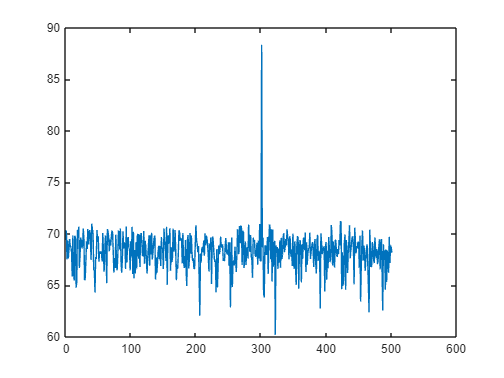

% Limpa registros (inclusive erros), confirmando que a lista de
% erros está vazia. Atentar à resposta padrão '0, "No error"'.
write(socket, [uint8('*CLS') 10], 'uint8')
[errorBinary1, error1] = WriteAndRead(socket, spec.('scpiStatus'))

% Envia comandos não reconhecidos pelo instrumento:
write(socket, [uint8('FREQuency:ISTOP?') 10], 'uint8')
write(socket, [uint8('FREQuency:ISTART?') 10], 'uint8')

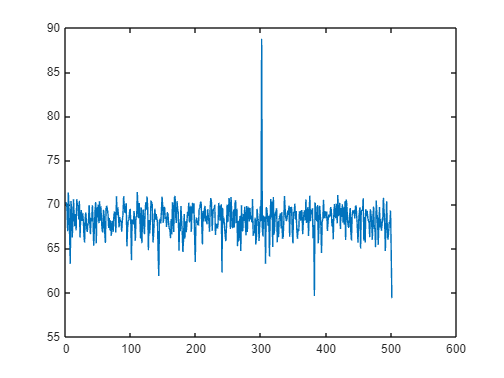


% Lê os erros:
[errorBinary2, error2] = WriteAndRead(socket, spec.('scpiStatus'))
[errorBinary3, error3] = WriteAndRead(socket, spec.('scpiStatus'))
[errorBinary4, error4] = WriteAndRead(socket, spec.('scpiStatus'))

#### **Varredura**

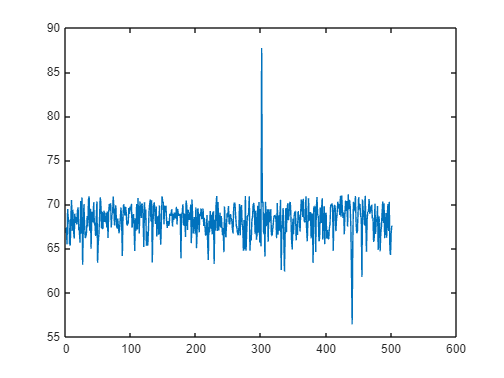

OnlyWrite(socket, spec.('StartUp'))
[sweepBinary, sweepTextual] = WriteAndRead(socket, spec.('scpiTraceData'))
% No caso específico desse bloco binário gerado pelo Tektronix SA2500, o seu tamanho é 2011 bytes, 
% sendo 6 bytes de cabeçalho, 2004 bytes representando os pontos da varredura e 1 byte de terminação.

% Em relação ao cabeçalho, 
% - O primeiro caractere é o identificador (será sempre "#");
% - O segundo caractere representa a codificação (no presente casa, "4" bytes por ponto); e
% - Os outros quatro caracteres representa o número total de bytes do bloco binário que representa os pontos.


% Dessa forma, deduz-se o número de pontos entregue por varredura: 2004/4 = 501.
blockHeader  = char(sweepBinary(1:6));

encoding     = str2double(blockHeader(2));
switch encoding
    case 4; encodingDataType = 'single';
    case 8; encodingDataType = 'double';
end

numberBytes  = str2double(blockHeader(3:6));
numberPoints = numberBytes / encoding;
sweepArray   = typecast(sweepBinary(7:numberBytes+6), encodingDataType);

ax  = axes(figure);
plt = plot(ax, sweepArray);

#### Varredura (plot), usando a função de teste (WriteAndRead)

hold(ax, 'on');

for ii = 1:10
    sweepBinary = WriteAndRead(socket, spec.('scpiTraceData'));
    sweepArray  = typecast(sweepBinary(7:numberBytes+6), encodingDataType);
    
    plt.YData = sweepArray;
    drawnow
end

#### Varredura (plot), usando a função usada no appColeta (readbinblock)

hold(ax, 'on');

for ii = 1:10
    writeline(socket, spec.('scpiTraceData'));
    sweepArray = readbinblock(socket, "single");
    
    plt.YData = sweepArray;
    drawnow
end